## Tensor Train (TT) decomposition

The tensor train decomposition consists in splitting an $N$-order tensor into a sequence of contraction products among two matrices and $N-2$ third-order tensors.

Suppose that $\underline{\mathbf{X}}$ be an N-order tensor,in the tensor network representation, $\underline{\mathbf{X}}$ is

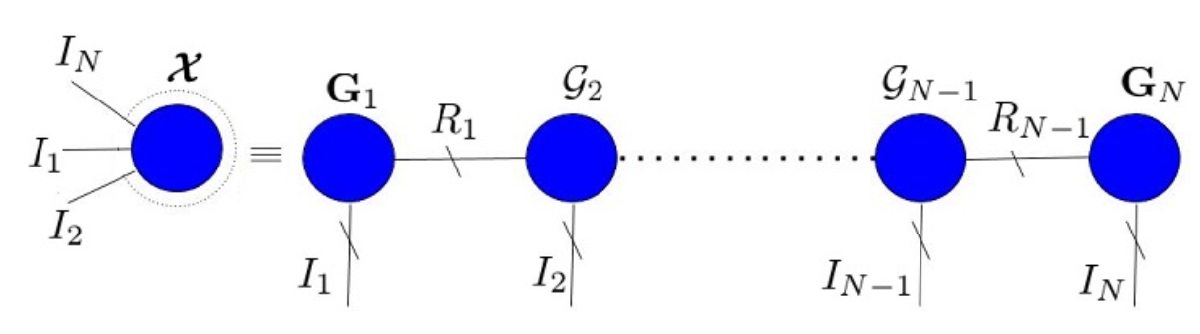

Mathematically, $\underline{\mathbf{X}}$ is given by


$$\underline{\mathbf{X}} ={\mathbf{G}}_1 \bullet_2^1 \;{\underline{\mathbf{G}} }_2 \;\bullet_3^1 \;{\underline{\mathbf{G}} }_3 \bullet_3^1 \cdots \bullet_3^1 \;{\underline{\mathbf{G}} }_{N-1} \bullet_3^1 \;{\mathbf{G}}_N$$


where $\underline{\mathbf{X}} \in C^{I_1 \times I_2 \times \cdots \times I_N }$, ${\mathbf{G}}_1 \in C^{I_1 \times R_1 }$, ${\mathbf{G}}_N \in C^{I_N \times R_{N-1} }$, and ${\underline{\mathbf{G}} }_i \in C^{R_{i-1} \times I_i \times R_i }$ for $2\le i\le N-1$, being $\left\lbrace R_1 ,R_2 ,\cdots ,\;R_{N-1} \right\rbrace$ the TT rank of the decomposition. The set $\left\lbrace {\mathbf{G}}_1 ,\;{\underline{\mathbf{G}} }_2 ,\;\;{\underline{\mathbf{G}} }_3 ,\cdots ,{\underline{\mathbf{G}} }_{N-1} ,\;{\mathbf{G}}_N \right\rbrace$ represents the TT decomposition of $\underline{\mathbf{X}}$.

Advantages:

- The TT decomposition has an advantage over the THOSVD as it decreases the dimensionality of the tensor from $N$ to $3$. In contrast, the core tensor of the THOSVD is still an $N$-order tensor.

- The TT decomposition is an attractive approach for high-order problems.

- Its storage cost grows linearly with $N$, which is a smooth growth when compared with other methods.

Quirks:

- In practice, the TT decomposition is implemented with the so-called TT-SVD algorithm.

- As the tensor network has a linear fashion, the algorithm cannot be parallelized.

Disadvantages

- The computation cost of the TT decomposition is high.

### Problem 1

Let us define the matrices ${\mathbf{G}}_1 \in C^{5\times 3}$, ${\mathbf{G}}_4 \in C^{3\times 5}$ and by the tensors ${\underline{\mathbf{G}} }_2 ,{\underline{\mathbf{G}} }_3 \in C^{3\times 5\times 3}$. All of these variables came from a Gaussian process. Let us further define 


$$\underline{\mathbf{X}} ={\mathbf{G}}_1 \bullet_2^1 \;{\underline{\mathbf{G}} }_2 \;\bullet_3^1 \;{\underline{\mathbf{G}} }_3 \bullet_3^1 \;{\mathbf{G}}_4 \in C^{5\times 5\times 5\times 5}$$


[G1, tenG2, tenG3, GN] = deal(randn([5, 3]), randn([3, 5, 3]), randn([3, 5, 3]), randn([3, 5]));
tenX = contrac_prod([G1, {tenG2, tenG3}, GN], {[2, 1], [3, 1], [3,1]});

If $\left\lbrace R_1 ,R_2 ,\;R_3 \right\rbrace =\left\lbrace 3,3,3\right\rbrace$, we have

R = 3;
[G1_hat, all_tenG_hat, GN_hat, all_S_hat] = tensor_train(tenX, [R, R, R]);
tenX_hat = contrac_prod([G1_hat, all_tenG_hat, GN_hat], {[2, 1], [3, 1], [3,1]});

The nomalized squared error is

norm(tensor(tenX - tenX_hat))/norm(tensor(tenX))

ans = 3.3748e-15

When $\left\lbrace R_1 ,R_2 ,\;R_3 \right\rbrace =\left\lbrace 2,2,2\right\rbrace$, we have

R =2;
[G1_hat, all_tenG_hat, GN_hat, ~] = tensor_train(tenX, [R, R, R]);
tenX_hat = contrac_prod([G1_hat, all_tenG_hat, GN_hat], {[2, 1], [3, 1], [3,1]});

The nomalized squared error is

norm(tensor(tenX - tenX_hat))/norm(tensor(tenX))

ans = 0.4296

Conclusions:

For a 4-dimensional tensor, it is possible to notice that the most significant singular values of the TT-SVD decompositions are the three first values, as it is shown bellow

all_S_hat{:}

ans =   244.8563         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  140.4603         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   

ans =   257.4061         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0  128.0804         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   79.9838         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0    0.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 

ans =   245.7797         0         0         0         0
         0  156.9672         0         0         0
         0         0   63.3526         0         0
         0         0         0    0.0000         0
         0         0         0         0    0.0000
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0
         0         0         0         0         0


Therefore, it is sensible to select the three first singular values in order to reconstruct the tensor properly. When only the two first values are selected, we lost a significant portion of the signal's energy.

### Problem 2

Let us define

$\underline{{\mathbf{X}}_0 } ={\mathbf{G}}_1 \bullet_2^1 \;{\underline{\mathbf{G}} }_2 \;\bullet_3^1 \;{\underline{\mathbf{G}} }_3 \bullet_3^1 \;{\mathbf{G}}_4 \in C^{5\times 5\times 5\times 5}$,

where ${\mathbf{G}}_1 \in C^{5\times 3}$, ${\mathbf{G}}_4 \in C^{3\times 5}$, and ${\underline{\mathbf{G}} }_2 ,{\underline{\mathbf{G}} }_3 \in C^{3\times 5\times 3}$, and $R=3$. All of these variables drawn from a normal distribution with mean equal to 0 and variance equal to 1.

Consider a noisy term, $\underline{\mathbf{V}}$, with same dimension of $\underline{{\mathbf{X}}_0 }$, whose components come from a normal distribution with the same statistics. Let us further define $\underline{\mathbf{X}} =\underline{{\mathbf{X}}_0 } +\alpha \underline{\mathbf{V}}$ as the noisy version of $\underline{{\mathbf{X}}_0 }$, where $\alpha$ is a parameter that is setted depending on the signal-to-noise ration in the system, given by


$${\textrm{SNR}}_{\textrm{dB}} =10\;\log_{10} \;\left(\frac{{\left\|\underline{{\mathbf{X}}_0 } \right\|}_F^2 }{{\left\|\alpha \underline{\mathbf{V}} \right\|}_F^2 }\right)\to \alpha =\frac{{\left\|{\mathbf{X}}_0 \right\|}_F^{\;} }{{\left\|\underline{\mathbf{V}} \right\|}_F^{\;} }\sqrt{{10}^{-\frac{{\textrm{SNR}}_{\textrm{dB}} }{10}} }$$


Compute the TT-SVD algorithm for the SNR for the range $\left\lbrack \begin{array}{ccccccc}
0 & 5 & 10 & 15 & 20 & 25 & 30
\end{array}\right\rbrack$ dB , find the estimates ${\hat{\mathbf{G}} }_1$, ${\hat{\mathbf{G}} }_4$, ${\underline{\hat{\mathbf{G}} } }_2$, and ${\underline{\hat{\mathbf{G}} } }_3$ obtained when $\left\lbrace R_1 ,R_2 ,R_3 \right\rbrace =\left\lbrace 3,3,3\right\rbrace$. The normalized mean square error (NMSE), given by


$$\textrm{NMSE}=\frac{1}{1000}\sum_i \frac{{\left\|\underline{\mathbf{X}} \left(i\right)-\underline{\hat{\mathbf{X}} } \left(i\right)\right\|}_F^2 }{{\left\|\underline{\mathbf{X}} \left(i\right)\right\|}_F^2 }\;,$$


is obtained after 1000 Monte Carlo experiments. The values ${\mathbf{G}}_1$, ${\mathbf{G}}_4$, ${\underline{\mathbf{G}} }_2$, ${\underline{\mathbf{G}} }_3$, and $\underline{\mathbf{V}}$ are generated randomly for each experiment.

R=3;
max = 5e2;
all_snr = 0:5:30;
all_nmse_X = zeros(length(all_snr), 1);
for snr=all_snr
    nmse_X = 0;
    for i=1:max
        % generating tenX0
        [G1, tenG2, tenG3, GN] = deal(randn([5, 3]), randn([3, 5, 3]), randn([3, 5, 3]), randn([3, 5]));
        tenX0 = contrac_prod([G1, {tenG2, tenG3}, GN], {[2, 1], [3, 1], [3,1]});
        % generating tenX
        tenV = randn(size(tenX0));
        alpha = sqrt(10^(-snr/10))* norm(tensor(tenX0))/ norm(tensor(tenV));
        tenX = tenX0 + alpha*tenV;
        % TT-SVD
        [G1_hat, all_tenG_hat, GN_hat, ~] = tensor_train(tenX, [R, R, R]);
        tenX_hat = contrac_prod([G1_hat, all_tenG_hat, GN_hat], {[2, 1], [3, 1], [3,1]});
        % NMSE X
        nmse_X = nmse_X + norm(tensor(tenX0 - tenX_hat))/norm(tensor(tenX0));
    end
    all_nmse_X(all_snr==snr) = nmse_X/max;
end

#### Ploting the results

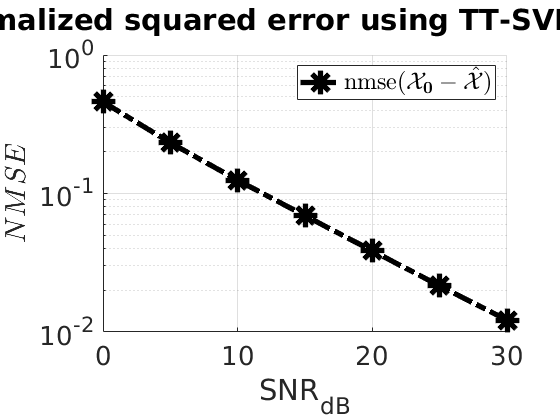

fig = figure();
ax = gca();
ax.FontName = 'Times New Roman';
ax.FontSize = 20;
ax.YAxis.Scale='log';
ax.XAxis.Label.String = 'SNR_{dB}';
ax.YAxis.Label.String = '$$NMSE$$';
ax.YAxis.Label.Interpreter = 'latex';
ax.Title.String = 'The normalized squared error using TT-SVD vs. SNR_{dB}';
grid on;
hold on;
plot(all_snr, all_nmse_X, 'LineWidth', 4, 'Color', "black","LineStyle","-.","Marker","*","MarkerSize",18);
legend('nmse$$(\mathbf{\mathcal{X}_0} - \hat{\mathbf{\mathcal{X}}})$$', 'Interpreter','latex');
hold off;

Discussion of the results:

- Non-uniqueness of the reconstructed tensor: As much as the tensor X can be properly reconstructed, the factors used to build it is not unique. It can the verified as shown bellow

norm(tensor(tenG2-all_tenG_hat{1}))/norm(tensor(tenG2))

ans = 1.0756

Indeed, the non-uniqueness can be easily proven.


$$\exists \;{\mathbf{M}}_q \in C^{R_q \times R_q } \;|\;{\underline{\tilde{\mathbf{G}} } }_q ={\underline{\mathbf{G}} }_q \bullet_3^1 {\mathbf{M}}_q ,\;{\underline{\tilde{\mathbf{G}} } }_{q+1} ={\mathbf{M}}_q \bullet_2^1 {\underline{\mathbf{G}} }_{q+1}$$


The tensors ${\underline{\tilde{\mathbf{G}} } }_q$ and ${\underline{\tilde{\mathbf{G}} } }_{q+1}$ can be replaced by ${\underline{\mathbf{G}} }_q$ and ${\underline{\mathbf{G}} }_{q+1}$, respectively, without change the final reconstruction.

function [G1, all_tenG, GN, all_S] = tensor_train(tenX, all_R)
all_tenG = cell(1, ndims(tenX)-2);
all_S = cell(1, numel(all_R));

% general matrix unfolding i==1
X_1 = reshape(tenX, size(tenX,1), []);
% SVD
[U,S,V_tilde] = svd(X_1);
all_S{1} = S;
% absorbing the value of S in V
V = S*V_tilde';
% truncating
[G1, Vt] = deal(U(:,1:all_R(1)), V(1:all_R(1),:));

[all_tenG, GN] = tt_rec(Vt, 2, all_R, all_tenG, size(tenX));

    function [all_tenG, GN] = tt_rec(Vt,i, all_R, all_tenG, all_I)
        X_i = reshape(Vt, [size(Vt,1)*all_I(i), prod(all_I(i+1:end))]);
        % SVD
        [U,S,V_tilde] = svd(X_i);
        all_S{i} = S;
        % absorbing the value of S in V
        V = S*V_tilde.';
        % truncating
        [Ut, Vt] = deal(U(:,1:all_R(i)), V(1:all_R(i),:));
        % generate tensor Gi
        all_tenG{i-1} = reshape(Ut, [all_R(i-1), all_I(i), all_R(i)]);
        if i<numel(all_I)-1 % compute the tensors G
            [all_tenG, GN] = tt_rec(Vt,i+1, all_R, all_tenG, all_I);
        else % compute GN
            GN = Vt;
        end
    end

end